convv = @(i,k,p,s) [(i(1)-k(1)+p(1)+s(1))/s(1) (i(2)-k(2)+p(2)+s(2))/s(2)];

convv([41 41],[15 15],[1 1],[1 1])

ans =     28    28


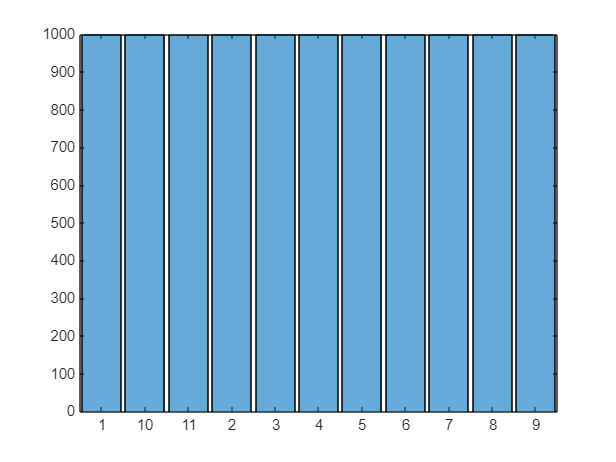

clear;clc;close all
% .mat
allImage = imageDatastore("data\win100_ov70", ...
    "FileExtensions",".mat", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames", ...
    "ReadFcn",@sig2scalogram);
histogram(allImage.Labels,unique(allImage.Labels))

clear;clc
% .jpg
allImage = imageDatastore("data_jpg_28_mag_u", ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");
% keep ch1 only (use @myDatastoreFunc)
logic = true(numel(allImage.Files),1);
logic(1:16:end) = false;
allImage.Files(logic) = [];
clear logic

% same data size
logic = true(numel(allImage.Files),1);
[classes,idx] = unique(allImage.Labels);
for i = 1:numel(classes)
    nData(i) = sum(allImage.Labels == classes(i));
end
for i = idx'
    logic(i:i+min(nData)) = false;
end
allImage.Files(logic) = [];
clear logic i idx nData classes
histogram(allImage.Labels,unique(allImage.Labels))

imgSize = size(allImage.read)

imgSize =    360   200     3


[trainDS, testDS] = splitEachLabel(allImage,0.8,"randomized");
nClass = numel(unique(trainDS.Labels))

nClass = 11

% all data
% data = image;
% label = categorical(repmat(["fist1" ;"fist0"],nSample/2,1));
% % spilt
% Xtrain = data(:,:,:,rndIdx(1:nTrainData));
% Ytrain = label(rndIdx(1:nTrainData));
% Xtest = data(:,:,:,rndIdx(nTrainData+1:end));
% Ytest = label(rndIdx(nTrainData+1:end));
% plot(layerGraph(layers))
net = imagePretrainedNetwork("googlenet","NumClasses",nClass)

Unrecognized function or variable 'nClass'.

Train Net

% net = MyNetworks(imgSize,nClass,"MobileNetv2")
net = imagePretrainedNetwork("googlenet","NumClasses",nClass)

net =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:01:54         0.01                            3.0281                                    11.682
            1        1       00:01:57         0.01          3.1421                                  12.5                      
           20        1       00:08:58         0.01          4.3601            4.5404              10.156                9.0909
           40        1       00:16:11         0.01          2.4427            2.4169              8.5938                8.8182
           50        1       00:19:15         0.01          2.4633                                8.5938                      
           60        1       00:23:16         0.01          2.4112            2.3924               9.375       

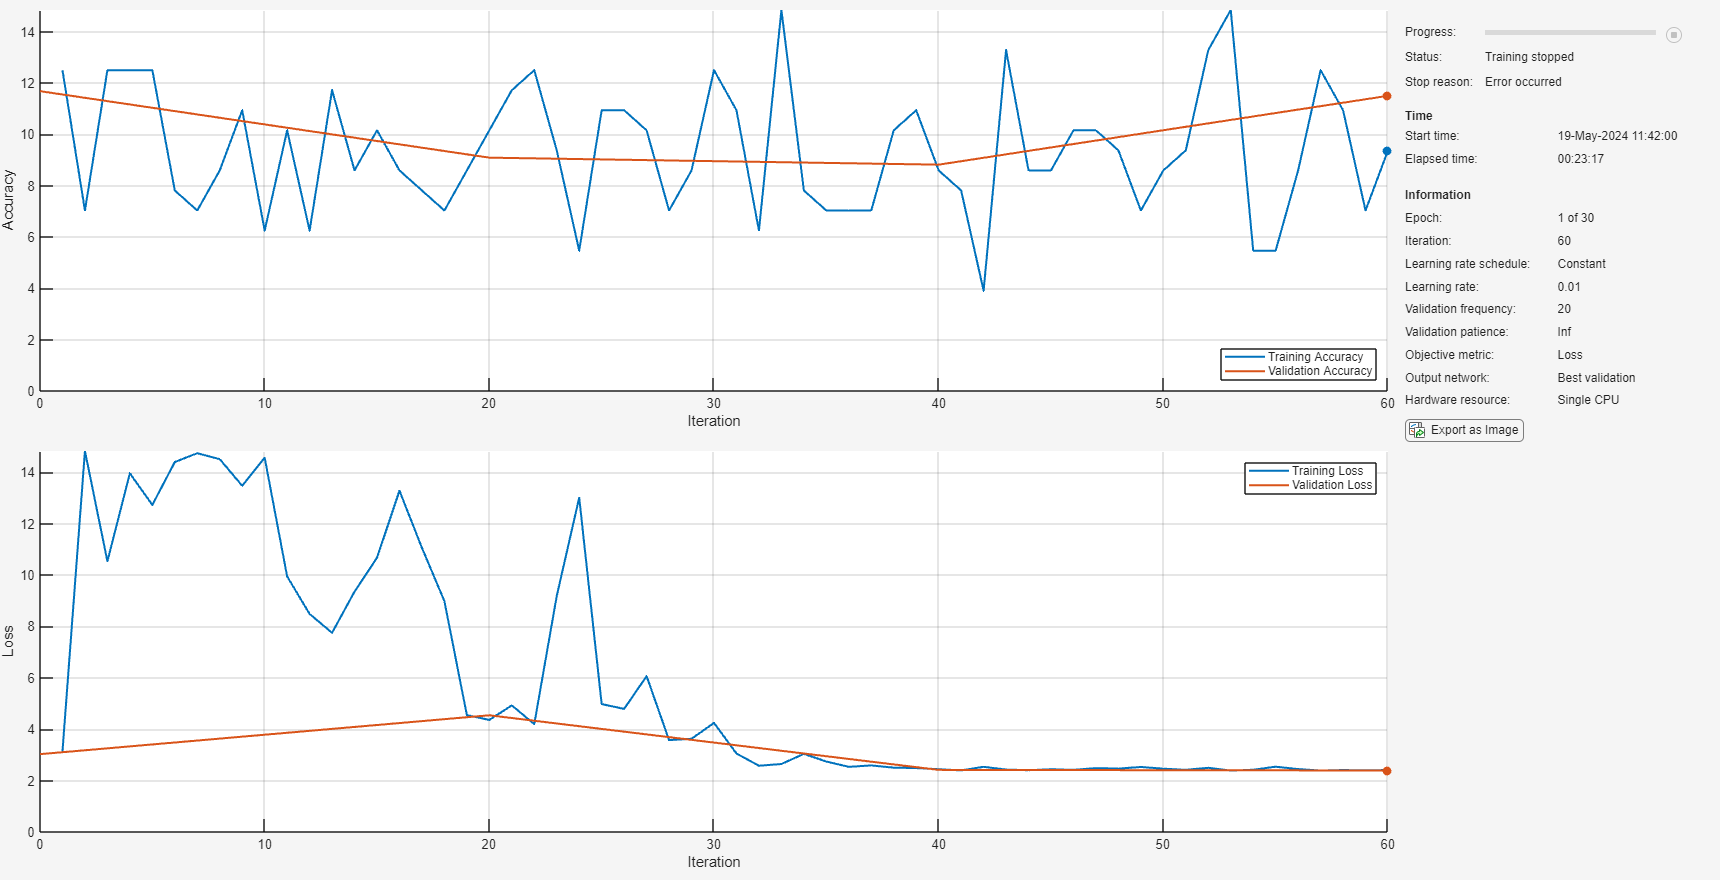

Error using deep.internal.train.Trainer/train (line 74)
Out of memory.

Error in deep.internal.train.trainnet (line 54)
net = train(trainer, net, mbq);

Error in trainnet (<a hr


options = trainingOptions('adam',...
    'MiniBatchSize',128,...
    'MaxEpochs',30,...
    'Verbose',1,...
    'ValidationFrequency',20,...
    'ExecutionEnvironment','auto',...
    'Plots','training-progress', ...
    'ValidationData',testDS, ...
    'InitialLearnRate',0.01,...
    'Metrics','accuracy');

trained_net = trainnet(trainDS,net,"crossentropy",options);

Train Network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:04:46         0.01                            2.7672
            1        1       00:04:55         0.01           2.743                  
Training stopped: Stopped manually


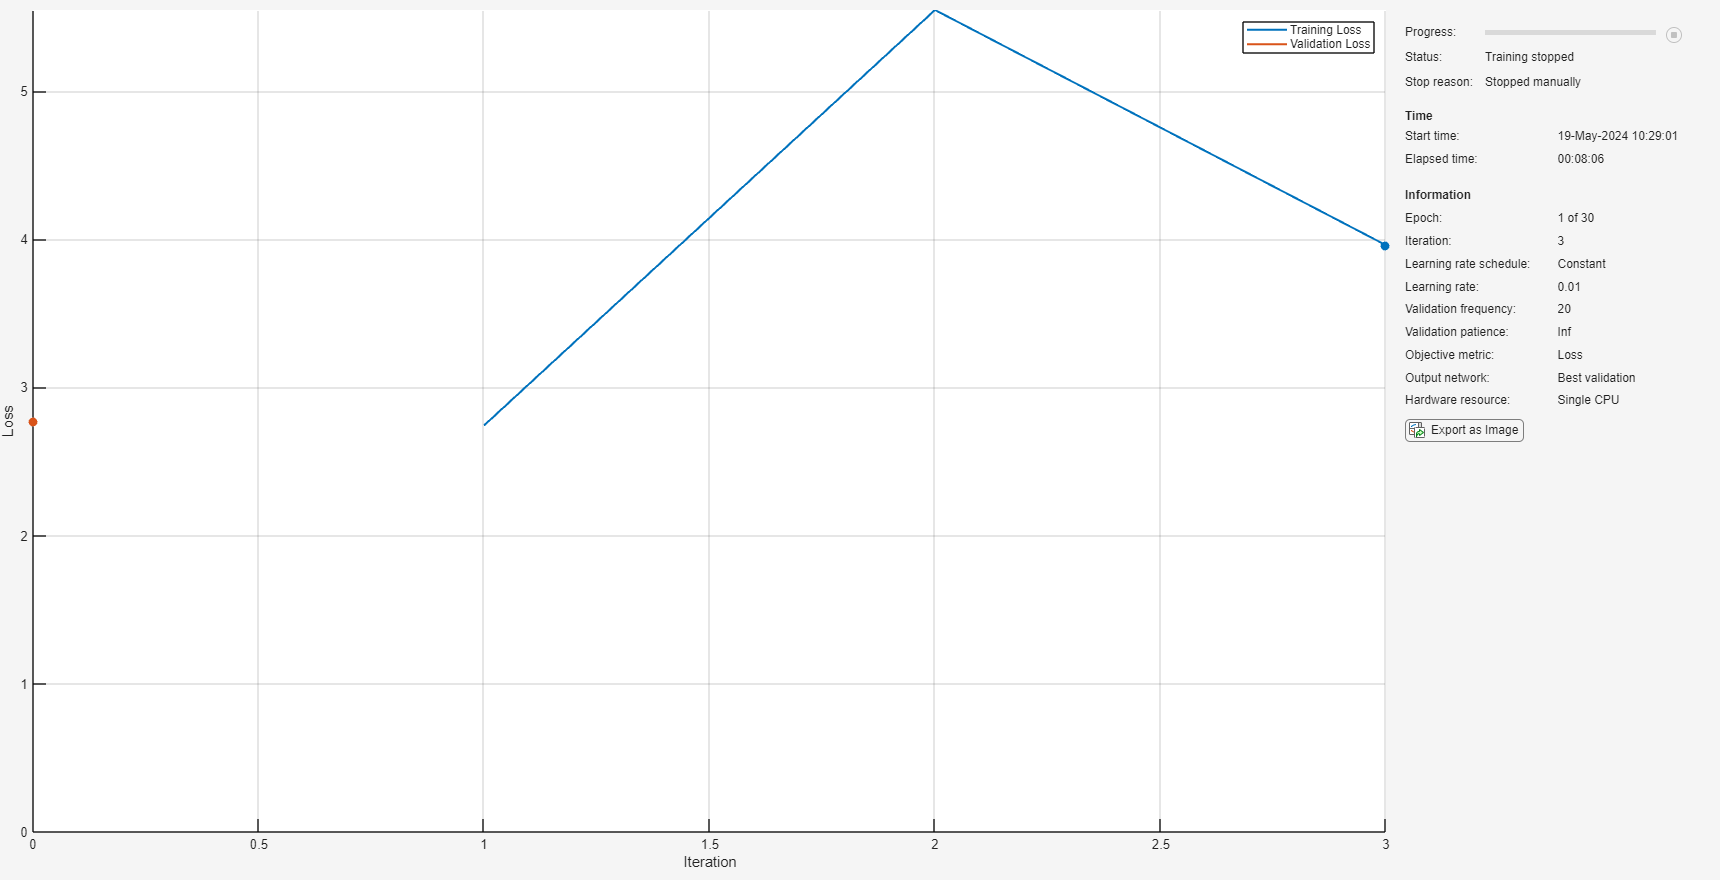

layers = MyNetworks(imgSize,nClass,1)

options = trainingOptions('adam',...
    'MiniBatchSize',128,...
    'MaxEpochs',30,...
    'Verbose',1,...
    'ValidationFrequency',20,...
    'ExecutionEnvironment','auto',...
    'Plots','training-progress', ...
    'ValidationData',testDS, ...
    'InitialLearnRate',0.01...
    );

trained_net = trainNetwork(trainDS,layers,options);


[Ypred,p] = classify(trainedNetwork_2,testDS);

Unrecognized function or variable 'testDS'.

mean(classify(trainedNetwork_3,trainDS)==trainDS.Labels)*100
mean(Ypred==testDS.Labels)*100
confusionchart(testDS.Labels,Ypred)

datastoreFunc(allImage.Files{1})

ans = 64×64×48 uint8 array
ans(:,:,1) =

     3     4     5     5     4     4     7     9    23    38    56    71    80    77    62    46    25    12    11    28    41    44    49    57    68    75    71    51    28    30    58    86   107   118   113    92    82    94   106   108   102    79    53    41    46    69   106   137   162   164   151   127   116   127   144   154   143   122    89    56    31    16     9     6
     2     3     4     4     3     4     6     9    22    37    56    72    81    79    64    49    30    18    16    30    39    39    43    52    69    76    77    61    43    44    68    93   114   119   106    78    65    80   101   109   100    82    61    50    54    74   109   138   165   165   143   107    91   110   139   154   146   125    91    56    30    14     6     3
     1     2     3     2     1     2     5     8    21    36    56    72    82    81    67    52    37    27    25    33    34    29    32    43    65    75    81    74    63    64    82   

allImage.read

ans =     0.1468    0.1699    0.2056    0.2446    0.2867    0.3405    0.4105    0.4822    0.5243    0.5055    0.4121    0.2648    0.1782    0.3041    0.4805    0.6317    0.7467    0.8183    0.8286    0.7581    0.6040    0.3937    0.2212    0.3278    0.6295    1.0524    1.6137    2.2839    2.9698    3.5406    3.8702    3.8809    3.5706    3.0149    2.3433    1.7043    1.2277    0.9711    0.8633    0.7810    0.6648    0.5168    0.3614    0.2210    0.1087    0.0727    0.1602    0.2889    0.4425    0.6060
    0.0327    0.0638    0.0960    0.1212    0.1455    0.1931    0.2785    0.3821    0.4692    0.5101    0.4971    0.4557    0.4373    0.4705    0.5323    0.5978    0.6649    0.7281    0.7623    0.7406    0.6606    0.5569    0.4911    0.5185    0.6808    1.0319    1.5910    2.3033    3.0493    3.6740    4.0307    4.0270    3.6568    3.0006    2.1981    1.4076    0.7856    0.5129    0.5688    0.6381    0.6165    0.5198    0.3852    0.2459    0.1262    0.0875    0.1819    0.3209    0.4844   

function img = myDatastoreFunc(fileName)
    imgFormatName = extractAfter(fileName,'.');
    imgAndChannel = extractBetween(fileName,'img_','.');
    imgNumber = extractBefore(imgAndChannel,'_');
    imgGroupName = extractBefore(fileName,strcat('img_',imgNumber));
    imgGroupName = strcat(imgGroupName,strcat('img_',imgNumber,'_'));
    for ch = 1:16
        img(:,:,ch) = imread(string(imgGroupName) + ch + "." + string(imgFormatName));
    end
end
function Image = sig2scalogram(fileName)
    img = load(fileName).img;
    fb = cwtfilterbank('SignalLength',size(img,1),'VoicesPerOctave',12);
    Image = [];
    c1=[];
    c2=[];
    % sf = waveletScattering('SignalLength',size(img,1),'SamplingFrequency',28);
    for ch = 1:size(img,2)
        % [S,U] = scatteringTransform(sf,img(:,ch));
        % x = scattergram(sf,S,'FilterBank',1)
        % scattergram(sf,U,'FilterBank',1)
        x = abs(fb.wt(img(:,ch)));
        x = rescale(x); % between [0,1]
        x = im2uint8(x); % not recommended for .mat (.jpg?)
        % x = imresize(x, imgSize); % resize

        % subplot(221);plot(img(:,ch))
        % subplot(222);imshow(x)
        % subplot(223);imshow(x1)
        % subplot(224);imshow(x2)

        % concat 1
        % Image = cat(3,Image,x);

        % concat 2
        % Image = cat(1,Image,x);

        % concat 3
        if rem(ch,2)==0
            c2 = cat(1,c2,x);
        else
            c1 = cat(1,c1,x);
        end
    end
    % concat 3
    Image = cat(2,c1,c2);
    % RGB
    Image = ind2rgb(Image,jet(256));

    % imshow(Image)
    % imahow(rescale(Image))
end